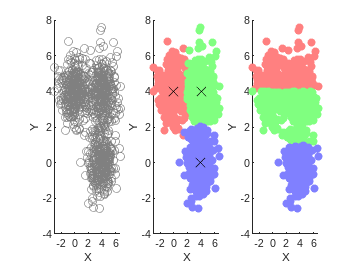

% Generate synthetic data
rng(0); % For reproducibility
N = 300; % Number of data points
data1 = randn(N,2) + [0, 4];
data2 = randn(N,2) + [4, 0];
data3 = randn(N,2) + [4, 4];
data = [data1; data2; data3]; % Combine data into one matrix

% Perform k-means clustering
k = 3; % Number of clusters
[idx, C] = kmeans(data, k);

% Create figure
figure;

% Plot original data
subplot(1,3,1);
scatter(data(:,1), data(:,2), 'MarkerEdgeColor', [0.5 0.5 0.5]);
xlabel('X');
ylabel('Y');

% Plot clustered data
subplot(1,3,2);
scatter(data(idx==1,1), data(idx==1,2), 36, [1 0.5 0.5], 'filled');
hold on;
scatter(data(idx==2,1), data(idx==2,2), 36, [0.5 1 0.5], 'filled');
scatter(data(idx==3,1), data(idx==3,2), 36, [0.5 0.5 1], 'filled');
scatter(C(:,1), C(:,2), 100, 'k', 'x'); % Plot cluster centers
hold off;
xlabel('X');
ylabel('Y');

% Classify based on Y-axis and plot
idx_y = zeros(size(data,1), 1);
idx_y(data(:,2) > 4) = 1;
idx_y(data(:,2) <= 4 & data(:,2) > 1) = 2;
idx_y(data(:,2) <= 1) = 3;

subplot(1,3,3);
scatter(data(idx_y==1,1), data(idx_y==1,2), 36, [1 0.5 0.5], 'filled');
hold on;
scatter(data(idx_y==2,1), data(idx_y==2,2), 36, [0.5 1 0.5], 'filled');
scatter(data(idx_y==3,1), data(idx_y==3,2), 36, [0.5 0.5 1], 'filled');
hold off;
xlabel('X');
ylabel('Y');